Calculate the enzyme production rate based on growth

dat3.enzyme_secretion = cell(size(dat3.biomass_delta));
[nrows,~] = size(dat3);
for i = 1:nrows
    biodelta = dat3.biomass_delta{i};
    a = dat3.alpha(i);
    enzdelta = biodelta * a;
    dat3.enzyme_secretion{i} = enzdelta;
end

%filter out some rows so trends are easier to see?
d = dat3;
filter4 = true;
%filter4=false;
if filter4
    loga = log10(dat3.alpha);
    keeps = -10:-1;
    d = d(ismember(loga,keeps),:);
end

Alpha which produced: -2 -1


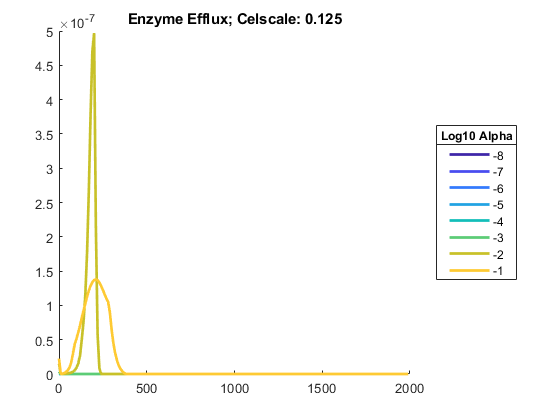

Alpha which produced: -2 -1


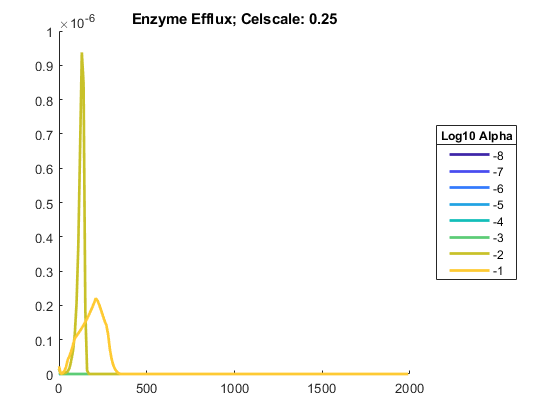

Alpha which produced: -3 -2 -1


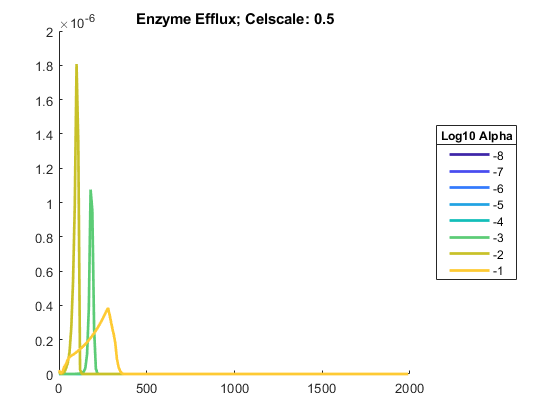

Alpha which produced: -3 -2 -1


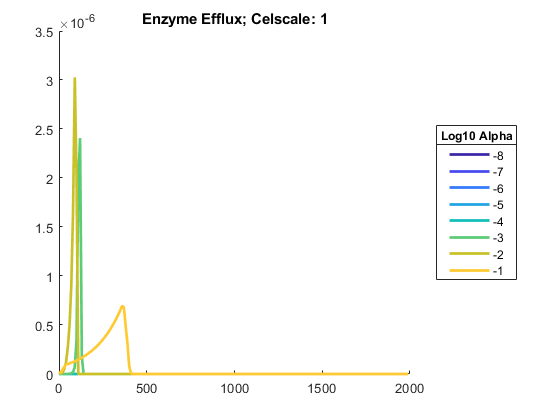

Alpha which produced: -3 -2 -1


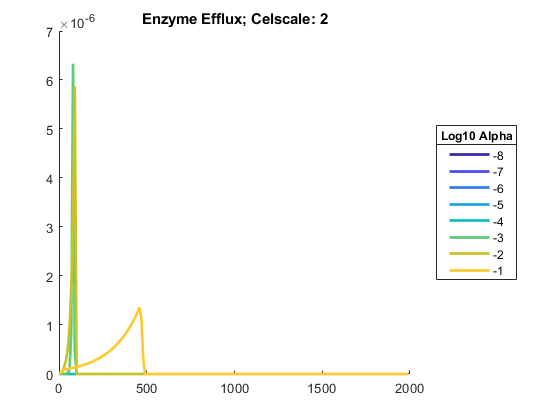

Alpha which produced: -4 -3 -2 -1


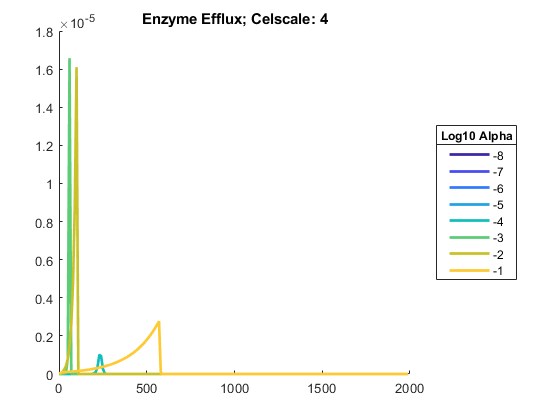

Alpha which produced: -4 -3 -2 -1


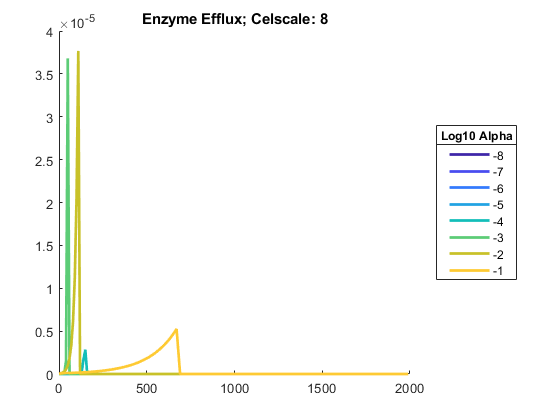

%plot the deltas
scales = unique(d.celscale);
threshold = 1e-8; %min efflux to report
for s = 1:length(scales)
    scale = scales(s);
    subdat = d(d.celscale == scale,:);
    [nrows,~] = size(subdat);
    figure();
    hold on;
    title(['Enzyme Efflux; Celscale: ' num2str(scale)]);
    colors = parula(nrows+1);
    didsecrete = [];
    for i = 1:nrows
        row = subdat(i,:);
        disppoints = zeros(size(row.t{1}));
        [runtime,~] = size(disppoints);
        [biodeltalength,~] = size(row.biomass_delta{1});
        runtime = min(runtime,biodeltalength);
        disppoints(1:10:runtime-1) = 1;
        plot(row.t{1}(disppoints==1),row.enzyme_secretion{1}(disppoints==1),'DisplayName',num2str(log10(row.alpha(1))),'LineWidth',2,'color',colors(i,:));
        if (max(row.enzyme_secretion{1}) > threshold)
            didsecrete = [didsecrete log10(row.alpha(1))];
        end
    end
    disp(['Alpha which produced: ' num2str(didsecrete)]);
    leg=legend('location','eastoutside');
    title(leg,'Log10 Alpha');
    hold off;
end

Compare maximum enzyme efflux with growth

dat3.enzyme_secretion_max = cellfun(@(x) max(x),dat3.enzyme_secretion);
t = table();